%% ======= MATLAB + Gurobi =========
% clear; clc;

%% ---- 用户参数 ----
i_ref = 100;     % 目标最终位置
L = 350;         % 序列长度
fs = 10e3;       % 采样频率
Ts = 1/fs;

% 频段/阈值设计
f_tol = 10;
f_min1 = 50 - f_tol;  f_max1 = 50 + f_tol;
f_min2 = 725 - f_tol; f_max2 = 725 + f_tol;
f_min3 = 825 - f_tol; f_max3 = 825 + f_tol;
ratio = 0.001;       % gamma = ratio * max_amp_init
% ratio = 0.0002;
% 位置/时间参数（用于 S 曲线）
t = (0:L-1)' * Ts;
T_end = L * Ts;

%% ---- 生成初始 S 曲线（和初始加速度） ----
A_mat = [ ...
    1, 0, 0,    0,      0,      0;
    1, T_end, T_end^2, T_end^3, T_end^4, T_end^5;
    0, 1, 0,    0,      0,      0;
    0, 1, 2*T_end, 3*T_end^2, 4*T_end^3, 5*T_end^4;
    0, 0, 2,    0,      0,      0;
    0, 0, 2,    6*T_end, 12*T_end^2, 20*T_end^3 ];
b = [0; i_ref; 0; 0; 0; 0];
coeffs = A_mat \ b;

i_dref = coeffs(1) + coeffs(2)*t + coeffs(3)*t.^2 + coeffs(4)*t.^3 + coeffs(5)*t.^4 + coeffs(6)*t.^5;
i_dref_vel = coeffs(2) + 2*coeffs(3)*t + 3*coeffs(4)*t.^2 + 4*coeffs(5)*t.^3 + 5*coeffs(6)*t.^4;
i_dref_accel = 2*coeffs(3) + 6*coeffs(4)*t + 12*coeffs(5)*t.^2 + 20*coeffs(6)*t.^3;

A_init = i_dref_accel;  % 初始加速度列向量 (L x 1)

%% ---- 构造 DFT 矩阵（rows: frequency bins 0..floor(Np/2)） ----
N_p = 2*2^nextpow2(L);      % 零填充长度
df = fs / N_p;
kvec = (0:floor(N_p/2))';     % 只使用单边频率 0..fs/2
nvec = 0:(L-1);

% F_sub: 每一行 k 对应一个频率，列对应时刻 n (L columns)
F_sub = exp(-1j * 2*pi * (kvec * nvec) / N_p);  % (floor(Np/2)+1) x L

f_single = (0:floor(N_p/2))' * df;  % 单边频率轴

% 初始频谱（单边）用于确定 gamma（常数 RHS）
Y_init = F_sub * A_init;                      % 单边频点的复数频谱
M_init = abs(Y_init) / N_p * 2;               % 单边幅值（与原脚本一致）
max_amp_init = max(M_init);
gamma = ratio * max_amp_init;                 % 原始尺度下的阈值
gamma_scaled = gamma / i_ref;                 % 归一化阈值（变量用 a = A / i_ref）

% 频段索引（限制在单边频率）
idx1 = find(f_single >= f_min1 & f_single <= f_max1);
idx2 = find(f_single >= f_min2 & f_single <= f_max2);
idx3 = find(f_single >= f_min3 & f_single <= f_max3);
idx_all = unique([idx1(:); idx2(:); idx3(:)]);
nIdx = numel(idx_all);

fprintf('Np=%d, #freq_bins=%d, max_amp_init=%.3e, gamma=%.3e, gamma_scaled=%.3e\n', ...
    N_p, length(f_single), max_amp_init, gamma, gamma_scaled);

Np=1024, #freq_bins=513, max_amp_init=1.702e+05, gamma=1.702e+02, gamma_scaled=1.702e+00



%% ---- 变量缩放：使用归一化变量 a = A / i_ref ----
% 这样能改善数值稳定性（避免 A 数值量级过大）
a_init = A_init / i_ref;

% 变量上下界（按原脚本，但做归一化）
A_lb = -500e7 * ones(L,1);
A_ub =  500e7 * ones(L,1);
a_lb = A_lb / i_ref;
a_ub = A_ub / i_ref;

%% ---- 构造 Gurobi 模型（变量为 a，规模 nvar = L） ----
nvar = L;
model.modelname = 'acc_fft_convex_scaled';
model.modelsense = 'min';   % 我们最小化 sum(a.^2)（等价于最小化 sum(A.^2)）

% bounds and var types
model.lb = a_lb;
model.ub = a_ub;
model.vtype = repmat('C', nvar, 1);
model.varnames = arrayfun(@(i) sprintf('a_%d',i), 1:nvar, 'UniformOutput', false);

% 二次目标: minimize sum(a.^2)
% Gurobi uses 0.5*x'Qx + c'x, to achieve sum(a.^2) set Q = 2*I
model.Q = sparse(1:nvar, 1:nvar, 2/1e5, nvar, nvar);
model.obj = zeros(nvar,1);

%% ---- 线性等式约束：末速度 = 0，末位置 = i_ref （变换后 RHS） ----
% 末速度: sum(A)/fs == 0  -> i_ref * sum(a) / fs == 0  -> sum(a) == 0
row1 = ones(1, L);

% 末位置: sum( A .* weights ) == i_ref
% weights = (L - i + 1) / fs^2
weights = ((L - (1:L) + 1)') / (fs^2);   % column vector Lx1
% substitute A = i_ref * a : i_ref * sum(a .* weights) == i_ref -> sum(a .* weights) == 1
row2 = weights.';      % 1 x L
Aeq = sparse([row1; row2]);   % 2 x L
model.A = Aeq;
model.rhs = [0; 1];           % 对归一化变量的 RHS： [0; 1]
model.sense = ['='; '='];     % 2 equalities

%% ---- 二次约束（频点幅值上界）： (Re(Fk*a))^2 + (Im(Fk*a))^2 <= gamma_scaled^2 ----
% 预先初始化 quadcon 的 struct 数组，字段一致，避免 "不同结构体下标赋值" 错误
model.quadcon = repmat(struct('Qc', sparse(nvar,nvar), 'q', sparse(nvar,1), ...
                              'rhs', 0, 'sense', '<', 'qcname', ''), nIdx, 1);

for ii = 1:nIdx
    kidx = idx_all(ii);     % 行索引到 F_sub
    Fk = F_sub(kidx, :);    % 1 x L
    ReFk = real(Fk);
    ImFk = imag(Fk);

    % Q_AA = ReFk'^ReFk + ImFk'^ImFk   (L x L, rank <= 2, PSD)
    Q_AA = (ReFk.' * ReFk) + (ImFk.' * ImFk);   % LxL

    model.quadcon(ii).Qc = sparse(Q_AA);
    model.quadcon(ii).q  = sparse(nvar,1);
    model.quadcon(ii).rhs = (gamma_scaled)^2;
    model.quadcon(ii).sense = '<';
    model.quadcon(ii).qcname = sprintf('freq_%.1fHz', f_single(kidx));
end

%% ---- 求解设置 ----
params.OutputFlag = 1; 
params.NumericFocus = 3; 
params.FeasibilityTol = 1e-3; % 保持较好可行性精度
% 不设置 IntFeasTol（无整数变量）
params.Method = 2;           % Barrier（对连续QCQP通常较好）
params.Crossover = 0;        % 禁用 crossover（节省时间）
params.BarConvTol = 1e-3;      % 收敛容差稍放宽
% try
tic;
result = gurobi(model, params);

Set parameter FeasibilityTol to value 0.001
Set parameter Method to value 2
Set parameter BarConvTol to value 0.001
Set parameter Crossover to value 0
Set parameter NumericFocus to value 3
Gurobi Optimizer version 11.0.3 build v11.0.3rc0 (win64 - Windows 11+.0 (26200.2))

CPU model: 13th Gen Intel(R) Core(TM) i9-13900H, instruction set [SSE2|AVX|AVX2]
Thread count: 14 physical cores, 20 logical processors, using up to 20 threads

Optimize a model with 2 rows, 350 columns and 700 nonzeros
Model fingerprint: 0x0b293a9b
Model has 350 quadratic objective terms
Model has 6 quadratic constraints
Coefficient statistics:
  Matrix range     [1e-08, 1e+00]
  QMatrix range    [1e-02, 2e+00]
  Objective range  [0e+00, 0e+00]
  QObjective range [4e-05, 4e-05]
  Bounds range     [5e+07, 5e+07]
  RHS range        [1e+00, 1e+00]
  QRHS range       [3e+00, 3e+00]
Presolve time: 0.08s
Presolved: 721 rows, 370 columns, 5602 n

toc

历时 0.742592 秒。


Gurobi 状态: OPTIMAL


末速度 V_end = 2.374873e-12 (期望 0)


末位置 I_end  = 1.000000e+02 (期望 i_ref = 1.000000e+02)


if isfield(result, 'x') && ~isempty(result.x)
    a_opt = result.x;
    A_opt = a_opt * i_ref;   % 恢复原始尺度
    fprintf('Gurobi 状态: %s\n', result.status);

    % 验证末速度、末位置
    V_end = sum(A_opt) / fs;
    I_end = sum( A_opt .* ((L - (1:L) + 1)') ) / (fs^2);
    fprintf('末速度 V_end = %.6e (期望 0)\n', V_end);
    fprintf('末位置 I_end  = %.6e (期望 i_ref = %.6e)\n', I_end, i_ref);

    %% 可视化（时域 + 频域对比）
    Y_opt = F_sub * A_opt;
    M_opt = abs(Y_opt) / N_p * 2;
    f_plot = f_single;

    figure;
    subplot(2,1,1);
    plot((0:L-1)'*Ts, A_init / i_ref, '--', 'LineWidth', 1); hold on;
    plot((0:L-1)'*Ts, A_opt / i_ref, '-', 'LineWidth', 1.2);
    legend('A\_init','A\_opt'); xlabel('Time (s)'); ylabel('a = A/i\_ref');
    title('时域：加速度（归一化）');

    subplot(2,1,2);
    plot(f_plot, M_init / i_ref, '--'); hold on;
    plot(f_plot, M_opt  / i_ref, '-');
    yline(gamma_scaled, 'r--', 'gamma\_scaled');
    xlim([0 1000]); xlabel('Frequency (Hz)'); ylabel('|A(f)|/i\_ref');
    legend('Before','After','Limit');
    grid on;
else
    fprintf('Gurobi 未返回解，状态 = %s\n', result.status);
    % 如果仍然出现 NUMERIC / INF / FAILED，可尝试以下建议（见下）
end


%% ---- 根据 A_opt 计算电流序列 i_d ----
v_opt = zeros(L,1);      % 初始化速度
I_opt   = zeros(L,1);      % 初始化电流

for k = 2:L
    v_opt(k) = v_opt(k-1) + A_opt(k) * Ts;   % 速度积分
    I_opt(k)   = I_opt(k-1) + v_opt(k) * Ts;    % 电流积分
end

% 验证最终值
fprintf('计算得到的末电流 i_d(end) = %.6f (目标 i_ref=%.6f)\n', I_opt(end), i_ref);

计算得到的末电流 i_d(end) = 98.053130 (目标 i_ref=100.000000)



% 可视化
figure;
subplot(3,1,1);
plot((0:L-1)*Ts, A_opt/ i_ref, 'LineWidth', 1.2); 
xlabel('t (s)'); ylabel('A (A/s^2)'); title('优化加速度 A\_opt');

subplot(3,1,2);
plot((0:L-1)*Ts, v_opt/ i_ref, 'LineWidth', 1.2);
xlabel('t (s)'); ylabel('v (A/s)'); title('积分后速度 v');

subplot(3,1,3);
plot((0:L-1)*Ts, I_opt/ i_ref, 'LineWidth', 1.5);
xlabel('t (s)'); ylabel('i_d (A)'); title('得到的电流轨迹 i\_d');
grid on;

extra = ones(5500, 1);
I_opt_ex =  [I_opt/i_ref; extra];
t_ex = (0:L-1+5500)' * Ts;
% 未处理的阶跃信号 I_step
I_step = ones(5500+L, 1);
ramp_signal = linspace(0, 1, L)';  % 在L步内从0线性增加到i_ref
% 组合信号：斜坡部分 + 恒定部分
I_ramp = ramp_signal;
I_ramp_ex = [I_ramp; ones(5500, 1)];

load("Tp_11.mat");
response1 = lsim(Tp_11, I_step, t_ex); % 阶跃响应
response2 = lsim(Tp_11, I_opt_ex, t_ex); % 优化后电流轨迹响应
response3 = lsim(Tp_11, I_ramp_ex, t_ex);

figure;
plot(t_ex, response1);hold on
plot(t_ex, response2);hold on
plot(t_ex, response3);

xlim([0,0.1]);
% ylim([0,3]);
legend('step','opt','ramp',Location='best');

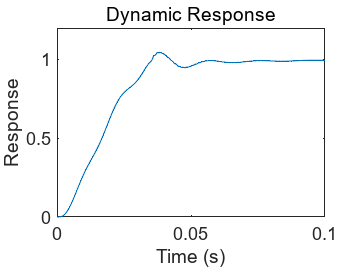

figure;
plot(t_ex, response2);ylim([0,1.2]);xlim([0,0.1]);
xlabel('Time (s)');
ylabel('Response');
title('Dynamic Response');